#### **LAB:4 **

#### **MD ZILAN UDDIN SAIF**

% Problem formulation
T=1; % sample time
kv=0.1; % parameter kv
kb=2; % parameter kb
a=exp(-kv*T); % parameter a (using exact discretization)
b=(1-exp(-kv*T))*kb/kv; % parameter b (using exact discretization)
c=kv; % parameter c
d=0; % parameter d
Q=0.1; % variance of system noise (disturbance)
R=0.1; % variance of measurement noise
x1=10;P1=0.2; % Initial conditions from estimation

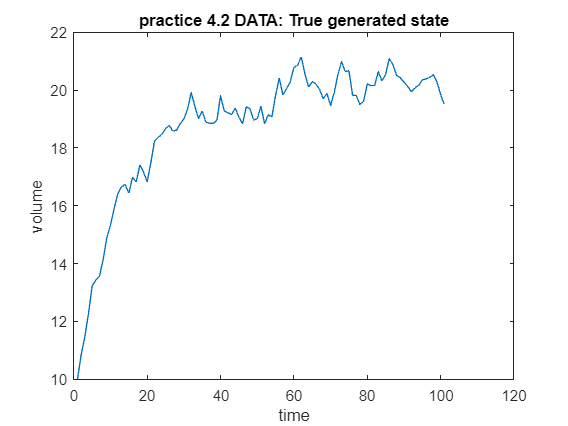

% generating data
rng(5); % initializing seed for random numbers
N=100; % number of data point
u=ones(N,1); % input vector
x=zeros(N+1,1); % initialization of states
y=zeros(N,1); % initialization of outputs
x(1)=x1; % initial condition

for k=1:N % data generation
x(k+1)=a*x(k)+b*u(k)+randn(1)*sqrt(Q); % state
y(k)=c*x(k)+d*u(k)+randn(1)*sqrt(R); % output
end
data=[u x(1:N) y];
save data2 data; % saving data (don't save x(N+1)
plot(x);
title('practice 4.2 DATA: True generated state')
xlabel('time')
ylabel('volume')

x = sdpvar(repmat(1,1,N+1),repmat(1,1,N+1));
objective = (x1-x{1})'*P1^(-1)*(x1-x{1}); % disturbance
constraints = [];
for k = 1:N
    objective = objective+...
    (x{k+1}-a*x{k}-b*u(k))'*Q^(-1)*(x{k+1}-a*x{k}-b*u(k))...
    +(y(k)-c*x{k})'*R^(-1)*(y(k)-c*x{k});
end
options = sdpsettings('solver','quadprog');
optimize(constraints,objective,options);


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


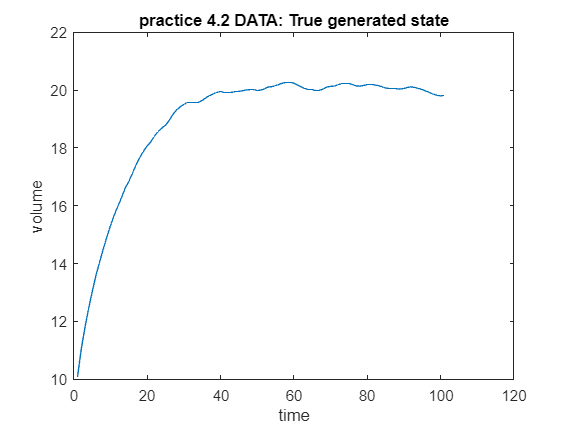

x_est = zeros(N+1,1);
for k = 1:N+1
x_est(k,1) = value(x{k});
end
plot(x_est);
title('practice 4.2 DATA: True generated state')
xlabel('time')
ylabel('volume')

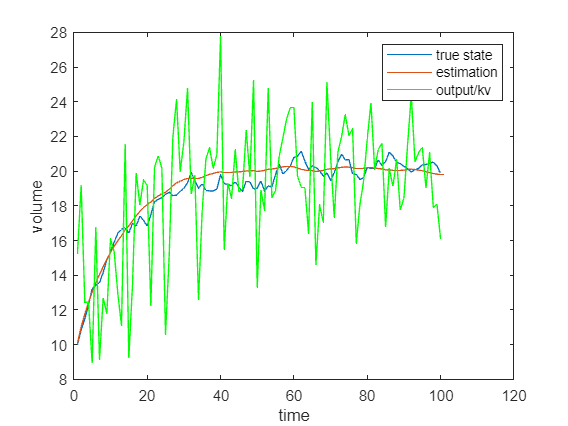

p = 0;
% for e = 0.1:0.1:2
p=p+1; % index for pareto plot

Q=0.1; % variance of system noise (disturbance)
R=0.1; % variance of measurement noise
x1=10;P1=0.2; % Initial conditions from estimation 
    figure
    plot(data(:,2));hold on
    plot(x_est)
    plot(y/kv,'g')
    legend('true state','estimation','output/kv')
    xlabel('time')
    ylabel('volume')

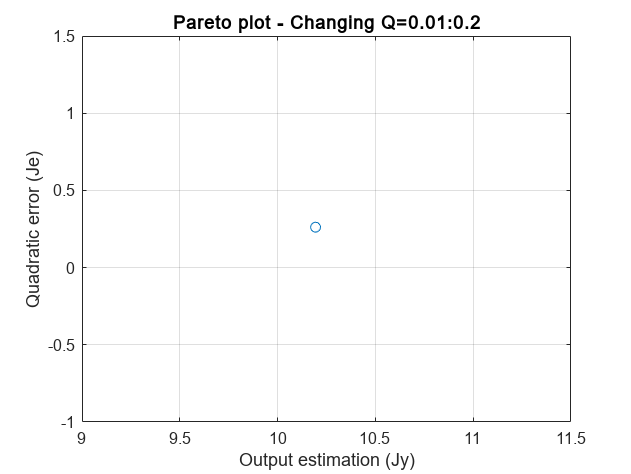



Je=0;
Jy=0;
for k=1:N
    w(k)=x_est(k+1)-(a*x_est(k)+b*u(k));    % System noise (disturbance)
    v(k)=y(k)-(c*x_est(k)+d*u(k));          % Measurement noise
    Je = Je + w(k)'*w(k);   % Quadratic error
    Jy = Jy + v(k)'*v(k);   % Output estimation
end

all_Je(p) = Je;
all_Jy(p) = Jy;

% end % end of for loop for pareto plot
figure
plot(all_Jy,all_Je,'o:')
title('Pareto plot - Changing Q=0.01:0.2')
xlabel('Output estimation (Jy)')
ylabel('Quadratic error (Je)')
grid on

x=zeros(N+1,1); % initialization of states
P=zeros(N+1,1); % initialization of P matrix
L=zeros(N,1); % initialization of L matrix
lb=zeros(N+1,1); % lower bounds of states
ub=zeros(N+1,1); % upper bounds of states
alpha=3 % select according confidence interval

alpha = 3

x(1)=x1; % initial condition for x;
P(1)=P1; % initial condition for P;
lb(1)=x(1)-sqrt(P(1))*1.96;
ub(1)=x(1)+sqrt(P(1))*1.96;
for k=1:N % codify Kalman filter in Matlab
L(k)=a*P(k)*c'/(R+c*P(k)*c');
    x(k+1)=a*x(k)+b*u(k)+L(k)*(y(k)-c*x(k));
    P(k+1)=Q+(a-L(k)*c)*P(k)*a';
lb(k+1)=x(k+1)-alpha*sqrt(P(k+1))
ub(k+1)=x(k+1)+alpha*sqrt(P(k+1))
end

lb =     9.1235
    9.5138
         0
         0
         0
         0
         0
         0
         0
         0


ub =    10.8765
   12.5764
         0
         0
         0
         0
         0
         0
         0
         0


lb =     9.1235
    9.5138
   10.4195
         0
         0
         0
         0
         0
         0
         0


ub =    10.8765
   12.5764
   13.7488
         0
         0
         0
         0
         0
         0
         0


lb =     9.1235
    9.5138
   10.4195
   11.0859
         0
         0
         0
         0
         0
         0


ub =    10.8765
   12.5764
   13.7488
   14.6078
         0
         0
         0
         0
         0
         0


lb =     9.1235
    9.5138
   10.4195
   11.0859
   11.6843
         0
         0
         0
         0
         0


ub =    10.8765
   12.5764
   13.7488
   14.6078
   15.3472
         0
         0
         0
         0
         0


lb =     9.1235
    9.5138
   10.4195
   11.0859
   11.6843
   12.1002
         0
         0
         0
         0


ub =    10.8765
   12.5764
   13.7488
   14.6078
   15.3472
   15.8672
         0
         0
         0
         0


lb =     9.1235
    9.5138
   10.4195
   11.0859
   11.6843
   12.1002
   12.7296
         0
         0
         0


ub =    10.8765
   12.5764
   13.7488
   14.6078
   15.3472
   15.8672
   16.5738
         0
         0
         0


lb =     9.1235
    9.5138
   10.4195
   11.0859
   11.6843
   12.1002
   12.7296
   13.0123
         0
         0


ub =    10.8765
   12.5764
   13.7488
   14.6078
   15.3472
   15.8672
   16.5738
   16.9138
         0
         0


lb =     9.1235
    9.5138
   10.4195
   11.0859
   11.6843
   12.1002
   12.7296
   13.0123
   13.3873
         0


ub =    10.8765
   12.5764
   13.7488
   14.6078
   15.3472
   15.8672
   16.5738
   16.9138
   17.3315
         0


lb =     9.1235
    9.5138
   10.4195
   11.0859
   11.6843
   12.1002
   12.7296
   13.0123
   13.3873
   13.6789


ub =    10.8765
   12.5764
   13.7488
   14.6078
   15.3472
   15.8672
   16.5738
   16.9138
   17.3315
   17.6550


lb =     9.1235
    9.5138
   10.4195
   11.0859
   11.6843
   12.1002
   12.7296
   13.0123
   13.3873
   13.6789


ub =    10.8765
   12.5764
   13.7488
   14.6078
   15.3472
   15.8672
   16.5738
   16.9138
   17.3315
   17.6550


lb =     9.1235
    9.5138
   10.4195
   11.0859
   11.6843
   12.1002
   12.7296
   13.0123
   13.3873
   13.6789


ub =    10.8765
   12.5764
   13.7488
   14.6078
   15.3472
   15.8672
   16.5738
   16.9138
   17.3315
   17.6550


lb =     9.1235
    9.5138
   10.4195
   11.0859
   11.6843
   12.1002
   12.7296
   13.0123
   13.3873
   13.6789


ub =    10.8765
   12.5764
   13.7488
   14.6078
   15.3472
   15.8672
   16.5738
   16.9138
   17.3315
   17.6550


lb =     9.1235
    9.5138
   10.4195
   11.0859
   11.6843
   12.1002
   12.7296
   13.0123
   13.3873
   13.6789


ub =    10.8765
   12.5764
   13.7488
   14.6078
   15.3472
   15.8672
   16.5738
   16.9138
   17.3315
   17.6550


lb =     9.1235
    9.5138
   10.4195
   11.0859
   11.6843
   12.1002
   12.7296
   13.0123
   13.3873
   13.6789


ub =    10.8765
   12.5764
   13.7488
   14.6078
   15.3472
   15.8672
   16.5738
   16.9138
   17.3315
   17.6550


lb =     9.1235
    9.5138
   10.4195
   11.0859
   11.6843
   12.1002
   12.7296
   13.0123
   13.3873
   13.6789


ub =    10.8765
   12.5764
   13.7488
   14.6078
   15.3472
   15.8672
   16.5738
   16.9138
   17.3315
   17.6550


lb =     9.1235
    9.5138
   10.4195
   11.0859
   11.6843
   12.1002
   12.7296
   13.0123
   13.3873
   13.6789


ub =    10.8765
   12.5764
   13.7488
   14.6078
   15.3472
   15.8672
   16.5738
   16.9138
   17.3315
   17.6550


lb =     9.1235
    9.5138
   10.4195
   11.0859
   11.6843
   12.1002
   12.7296
   13.0123
   13.3873
   13.6789


ub =    10.8765
   12.5764
   13.7488
   14.6078
   15.3472
   15.8672
   16.5738
   16.9138
   17.3315
   17.6550


lb =     9.1235
    9.5138
   10.4195
   11.0859
   11.6843
   12.1002
   12.7296
   13.0123
   13.3873
   13.6789


ub =    10.8765
   12.5764
   13.7488
   14.6078
   15.3472
   15.8672
   16.5738
   16.9138
   17.3315
   17.6550


lb =     9.1235
    9.5138
   10.4195
   11.0859
   11.6843
   12.1002
   12.7296
   13.0123
   13.3873
   13.6789


ub =    10.8765
   12.5764
   13.7488
   14.6078
   15.3472
   15.8672
   16.5738
   16.9138
   17.3315
   17.6550


lb =     9.1235
    9.5138
   10.4195
   11.0859
   11.6843
   12.1002
   12.7296
   13.0123
   13.3873
   13.6789


ub =    10.8765
   12.5764
   13.7488
   14.6078
   15.3472
   15.8672
   16.5738
   16.9138
   17.3315
   17.6550


lb =     9.1235
    9.5138
   10.4195
   11.0859
   11.6843
   12.1002
   12.7296
   13.0123
   13.3873
   13.6789


ub =    10.8765
   12.5764
   13.7488
   14.6078
   15.3472
   15.8672
   16.5738
   16.9138
   17.3315
   17.6550


lb =     9.1235
    9.5138
   10.4195
   11.0859
   11.6843
   12.1002
   12.7296
   13.0123
   13.3873
   13.6789


ub =    10.8765
   12.5764
   13.7488
   14.6078
   15.3472
   15.8672
   16.5738
   16.9138
   17.3315
   17.6550


lb =     9.1235
    9.5138
   10.4195
   11.0859
   11.6843
   12.1002
   12.7296
   13.0123
   13.3873
   13.6789


ub =    10.8765
   12.5764
   13.7488
   14.6078
   15.3472
   15.8672
   16.5738
   16.9138
   17.3315
   17.6550


lb =     9.1235
    9.5138
   10.4195
   11.0859
   11.6843
   12.1002
   12.7296
   13.0123
   13.3873
   13.6789


ub =    10.8765
   12.5764
   13.7488
   14.6078
   15.3472
   15.8672
   16.5738
   16.9138
   17.3315
   17.6550


lb =     9.1235
    9.5138
   10.4195
   11.0859
   11.6843
   12.1002
   12.7296
   13.0123
   13.3873
   13.6789


ub =    10.8765
   12.5764
   13.7488
   14.6078
   15.3472
   15.8672
   16.5738
   16.9138
   17.3315
   17.6550


lb = 101×1
    9.1235
    9.5138
   10.4195
   11.0859
   11.6843
   12.1002
   12.7296
   13.0123
   13.3873
   13.6789


ub = 101×1
   10.8765
   12.5764
   13.7488
   14.6078
   15.3472
   15.8672
   16.5738
   16.9138
   17.3315
   17.6550


lb = 101×1
    9.1235
    9.5138
   10.4195
   11.0859
   11.6843
   12.1002
   12.7296
   13.0123
   13.3873
   13.6789


ub = 101×1
   10.8765
   12.5764
   13.7488
   14.6078
   15.3472
   15.8672
   16.5738
   16.9138
   17.3315
   17.6550


lb = 101×1
    9.1235
    9.5138
   10.4195
   11.0859
   11.6843
   12.1002
   12.7296
   13.0123
   13.3873
   13.6789


ub = 101×1
   10.8765
   12.5764
   13.7488
   14.6078
   15.3472
   15.8672
   16.5738
   16.9138
   17.3315
   17.6550


lb = 101×1
    9.1235
    9.5138
   10.4195
   11.0859
   11.6843
   12.1002
   12.7296
   13.0123
   13.3873
   13.6789


ub = 101×1
   10.8765
   12.5764
   13.7488
   14.6078
   15.3472
   15.8672
   16.5738
   16.9138
   17.3315
   17.6550


lb = 101×1
    9.1235
    9.5138
   10.4195
   11.0859
   11.6843
   12.1002
   12.7296
   13.0123
   13.3873
   13.6789


ub = 101×1
   10.8765
   12.5764
   13.7488
   14.6078
   15.3472
   15.8672
   16.5738
   16.9138
   17.3315
   17.6550


lb = 101×1
    9.1235
    9.5138
   10.4195
   11.0859
   11.6843
   12.1002
   12.7296
   13.0123
   13.3873
   13.6789


ub = 101×1
   10.8765
   12.5764
   13.7488
   14.6078
   15.3472
   15.8672
   16.5738
   16.9138
   17.3315
   17.6550


lb = 101×1
    9.1235
    9.5138
   10.4195
   11.0859
   11.6843
   12.1002
   12.7296
   13.0123
   13.3873
   13.6789


ub = 101×1
   10.8765
   12.5764
   13.7488
   14.6078
   15.3472
   15.8672
   16.5738
   16.9138
   17.3315
   17.6550


lb = 101×1
    9.1235
    9.5138
   10.4195
   11.0859
   11.6843
   12.1002
   12.7296
   13.0123
   13.3873
   13.6789


ub = 101×1
   10.8765
   12.5764
   13.7488
   14.6078
   15.3472
   15.8672
   16.5738
   16.9138
   17.3315
   17.6550


lb = 101×1
    9.1235
    9.5138
   10.4195
   11.0859
   11.6843
   12.1002
   12.7296
   13.0123
   13.3873
   13.6789


ub = 101×1
   10.8765
   12.5764
   13.7488
   14.6078
   15.3472
   15.8672
   16.5738
   16.9138
   17.3315
   17.6550


lb = 101×1
    9.1235
    9.5138
   10.4195
   11.0859
   11.6843
   12.1002
   12.7296
   13.0123
   13.3873
   13.6789


ub = 101×1
   10.8765
   12.5764
   13.7488
   14.6078
   15.3472
   15.8672
   16.5738
   16.9138
   17.3315
   17.6550


lb = 101×1
    9.1235
    9.5138
   10.4195
   11.0859
   11.6843
   12.1002
   12.7296
   13.0123
   13.3873
   13.6789


ub = 101×1
   10.8765
   12.5764
   13.7488
   14.6078
   15.3472
   15.8672
   16.5738
   16.9138
   17.3315
   17.6550


lb = 101×1
    9.1235
    9.5138
   10.4195
   11.0859
   11.6843
   12.1002
   12.7296
   13.0123
   13.3873
   13.6789


ub = 101×1
   10.8765
   12.5764
   13.7488
   14.6078
   15.3472
   15.8672
   16.5738
   16.9138
   17.3315
   17.6550


lb = 101×1
    9.1235
    9.5138
   10.4195
   11.0859
   11.6843
   12.1002
   12.7296
   13.0123
   13.3873
   13.6789


ub = 101×1
   10.8765
   12.5764
   13.7488
   14.6078
   15.3472
   15.8672
   16.5738
   16.9138
   17.3315
   17.6550


lb = 101×1
    9.1235
    9.5138
   10.4195
   11.0859
   11.6843
   12.1002
   12.7296
   13.0123
   13.3873
   13.6789


ub = 101×1
   10.8765
   12.5764
   13.7488
   14.6078
   15.3472
   15.8672
   16.5738
   16.9138
   17.3315
   17.6550


lb = 101×1
    9.1235
    9.5138
   10.4195
   11.0859
   11.6843
   12.1002
   12.7296
   13.0123
   13.3873
   13.6789


ub = 101×1
   10.8765
   12.5764
   13.7488
   14.6078
   15.3472
   15.8672
   16.5738
   16.9138
   17.3315
   17.6550


lb = 101×1
    9.1235
    9.5138
   10.4195
   11.0859
   11.6843
   12.1002
   12.7296
   13.0123
   13.3873
   13.6789


ub = 101×1
   10.8765
   12.5764
   13.7488
   14.6078
   15.3472
   15.8672
   16.5738
   16.9138
   17.3315
   17.6550


lb = 101×1
    9.1235
    9.5138
   10.4195
   11.0859
   11.6843
   12.1002
   12.7296
   13.0123
   13.3873
   13.6789


ub = 101×1
   10.8765
   12.5764
   13.7488
   14.6078
   15.3472
   15.8672
   16.5738
   16.9138
   17.3315
   17.6550


lb = 101×1
    9.1235
    9.5138
   10.4195
   11.0859
   11.6843
   12.1002
   12.7296
   13.0123
   13.3873
   13.6789


ub = 101×1
   10.8765
   12.5764
   13.7488
   14.6078
   15.3472
   15.8672
   16.5738
   16.9138
   17.3315
   17.6550


lb = 101×1
    9.1235
    9.5138
   10.4195
   11.0859
   11.6843
   12.1002
   12.7296
   13.0123
   13.3873
   13.6789


ub = 101×1
   10.8765
   12.5764
   13.7488
   14.6078
   15.3472
   15.8672
   16.5738
   16.9138
   17.3315
   17.6550


lb = 101×1
    9.1235
    9.5138
   10.4195
   11.0859
   11.6843
   12.1002
   12.7296
   13.0123
   13.3873
   13.6789


ub = 101×1
   10.8765
   12.5764
   13.7488
   14.6078
   15.3472
   15.8672
   16.5738
   16.9138
   17.3315
   17.6550


lb = 101×1
    9.1235
    9.5138
   10.4195
   11.0859
   11.6843
   12.1002
   12.7296
   13.0123
   13.3873
   13.6789


ub = 101×1
   10.8765
   12.5764
   13.7488
   14.6078
   15.3472
   15.8672
   16.5738
   16.9138
   17.3315
   17.6550


lb = 101×1
    9.1235
    9.5138
   10.4195
   11.0859
   11.6843
   12.1002
   12.7296
   13.0123
   13.3873
   13.6789


ub = 101×1
   10.8765
   12.5764
   13.7488
   14.6078
   15.3472
   15.8672
   16.5738
   16.9138
   17.3315
   17.6550


lb = 101×1
    9.1235
    9.5138
   10.4195
   11.0859
   11.6843
   12.1002
   12.7296
   13.0123
   13.3873
   13.6789


ub = 101×1
   10.8765
   12.5764
   13.7488
   14.6078
   15.3472
   15.8672
   16.5738
   16.9138
   17.3315
   17.6550


lb = 101×1
    9.1235
    9.5138
   10.4195
   11.0859
   11.6843
   12.1002
   12.7296
   13.0123
   13.3873
   13.6789


ub = 101×1
   10.8765
   12.5764
   13.7488
   14.6078
   15.3472
   15.8672
   16.5738
   16.9138
   17.3315
   17.6550


lb = 101×1
    9.1235
    9.5138
   10.4195
   11.0859
   11.6843
   12.1002
   12.7296
   13.0123
   13.3873
   13.6789


ub = 101×1
   10.8765
   12.5764
   13.7488
   14.6078
   15.3472
   15.8672
   16.5738
   16.9138
   17.3315
   17.6550


lb = 101×1
    9.1235
    9.5138
   10.4195
   11.0859
   11.6843
   12.1002
   12.7296
   13.0123
   13.3873
   13.6789


ub = 101×1
   10.8765
   12.5764
   13.7488
   14.6078
   15.3472
   15.8672
   16.5738
   16.9138
   17.3315
   17.6550


lb = 101×1
    9.1235
    9.5138
   10.4195
   11.0859
   11.6843
   12.1002
   12.7296
   13.0123
   13.3873
   13.6789


ub = 101×1
   10.8765
   12.5764
   13.7488
   14.6078
   15.3472
   15.8672
   16.5738
   16.9138
   17.3315
   17.6550


lb = 101×1
    9.1235
    9.5138
   10.4195
   11.0859
   11.6843
   12.1002
   12.7296
   13.0123
   13.3873
   13.6789


ub = 101×1
   10.8765
   12.5764
   13.7488
   14.6078
   15.3472
   15.8672
   16.5738
   16.9138
   17.3315
   17.6550


lb = 101×1
    9.1235
    9.5138
   10.4195
   11.0859
   11.6843
   12.1002
   12.7296
   13.0123
   13.3873
   13.6789


ub = 101×1
   10.8765
   12.5764
   13.7488
   14.6078
   15.3472
   15.8672
   16.5738
   16.9138
   17.3315
   17.6550


lb = 101×1
    9.1235
    9.5138
   10.4195
   11.0859
   11.6843
   12.1002
   12.7296
   13.0123
   13.3873
   13.6789


ub = 101×1
   10.8765
   12.5764
   13.7488
   14.6078
   15.3472
   15.8672
   16.5738
   16.9138
   17.3315
   17.6550


lb = 101×1
    9.1235
    9.5138
   10.4195
   11.0859
   11.6843
   12.1002
   12.7296
   13.0123
   13.3873
   13.6789


ub = 101×1
   10.8765
   12.5764
   13.7488
   14.6078
   15.3472
   15.8672
   16.5738
   16.9138
   17.3315
   17.6550


lb = 101×1
    9.1235
    9.5138
   10.4195
   11.0859
   11.6843
   12.1002
   12.7296
   13.0123
   13.3873
   13.6789


ub = 101×1
   10.8765
   12.5764
   13.7488
   14.6078
   15.3472
   15.8672
   16.5738
   16.9138
   17.3315
   17.6550


lb = 101×1
    9.1235
    9.5138
   10.4195
   11.0859
   11.6843
   12.1002
   12.7296
   13.0123
   13.3873
   13.6789


ub = 101×1
   10.8765
   12.5764
   13.7488
   14.6078
   15.3472
   15.8672
   16.5738
   16.9138
   17.3315
   17.6550


lb = 101×1
    9.1235
    9.5138
   10.4195
   11.0859
   11.6843
   12.1002
   12.7296
   13.0123
   13.3873
   13.6789


ub = 101×1
   10.8765
   12.5764
   13.7488
   14.6078
   15.3472
   15.8672
   16.5738
   16.9138
   17.3315
   17.6550


lb = 101×1
    9.1235
    9.5138
   10.4195
   11.0859
   11.6843
   12.1002
   12.7296
   13.0123
   13.3873
   13.6789


ub = 101×1
   10.8765
   12.5764
   13.7488
   14.6078
   15.3472
   15.8672
   16.5738
   16.9138
   17.3315
   17.6550


lb = 101×1
    9.1235
    9.5138
   10.4195
   11.0859
   11.6843
   12.1002
   12.7296
   13.0123
   13.3873
   13.6789


ub = 101×1
   10.8765
   12.5764
   13.7488
   14.6078
   15.3472
   15.8672
   16.5738
   16.9138
   17.3315
   17.6550


lb = 101×1
    9.1235
    9.5138
   10.4195
   11.0859
   11.6843
   12.1002
   12.7296
   13.0123
   13.3873
   13.6789


ub = 101×1
   10.8765
   12.5764
   13.7488
   14.6078
   15.3472
   15.8672
   16.5738
   16.9138
   17.3315
   17.6550


lb = 101×1
    9.1235
    9.5138
   10.4195
   11.0859
   11.6843
   12.1002
   12.7296
   13.0123
   13.3873
   13.6789


ub = 101×1
   10.8765
   12.5764
   13.7488
   14.6078
   15.3472
   15.8672
   16.5738
   16.9138
   17.3315
   17.6550


lb = 101×1
    9.1235
    9.5138
   10.4195
   11.0859
   11.6843
   12.1002
   12.7296
   13.0123
   13.3873
   13.6789


ub = 101×1
   10.8765
   12.5764
   13.7488
   14.6078
   15.3472
   15.8672
   16.5738
   16.9138
   17.3315
   17.6550


lb = 101×1
    9.1235
    9.5138
   10.4195
   11.0859
   11.6843
   12.1002
   12.7296
   13.0123
   13.3873
   13.6789


ub = 101×1
   10.8765
   12.5764
   13.7488
   14.6078
   15.3472
   15.8672
   16.5738
   16.9138
   17.3315
   17.6550


lb = 101×1
    9.1235
    9.5138
   10.4195
   11.0859
   11.6843
   12.1002
   12.7296
   13.0123
   13.3873
   13.6789


ub = 101×1
   10.8765
   12.5764
   13.7488
   14.6078
   15.3472
   15.8672
   16.5738
   16.9138
   17.3315
   17.6550


lb = 101×1
    9.1235
    9.5138
   10.4195
   11.0859
   11.6843
   12.1002
   12.7296
   13.0123
   13.3873
   13.6789


ub = 101×1
   10.8765
   12.5764
   13.7488
   14.6078
   15.3472
   15.8672
   16.5738
   16.9138
   17.3315
   17.6550


lb = 101×1
    9.1235
    9.5138
   10.4195
   11.0859
   11.6843
   12.1002
   12.7296
   13.0123
   13.3873
   13.6789


ub = 101×1
   10.8765
   12.5764
   13.7488
   14.6078
   15.3472
   15.8672
   16.5738
   16.9138
   17.3315
   17.6550


lb = 101×1
    9.1235
    9.5138
   10.4195
   11.0859
   11.6843
   12.1002
   12.7296
   13.0123
   13.3873
   13.6789


ub = 101×1
   10.8765
   12.5764
   13.7488
   14.6078
   15.3472
   15.8672
   16.5738
   16.9138
   17.3315
   17.6550


lb = 101×1
    9.1235
    9.5138
   10.4195
   11.0859
   11.6843
   12.1002
   12.7296
   13.0123
   13.3873
   13.6789


ub = 101×1
   10.8765
   12.5764
   13.7488
   14.6078
   15.3472
   15.8672
   16.5738
   16.9138
   17.3315
   17.6550


lb = 101×1
    9.1235
    9.5138
   10.4195
   11.0859
   11.6843
   12.1002
   12.7296
   13.0123
   13.3873
   13.6789


ub = 101×1
   10.8765
   12.5764
   13.7488
   14.6078
   15.3472
   15.8672
   16.5738
   16.9138
   17.3315
   17.6550


lb = 101×1
    9.1235
    9.5138
   10.4195
   11.0859
   11.6843
   12.1002
   12.7296
   13.0123
   13.3873
   13.6789


ub = 101×1
   10.8765
   12.5764
   13.7488
   14.6078
   15.3472
   15.8672
   16.5738
   16.9138
   17.3315
   17.6550


lb = 101×1
    9.1235
    9.5138
   10.4195
   11.0859
   11.6843
   12.1002
   12.7296
   13.0123
   13.3873
   13.6789


ub = 101×1
   10.8765
   12.5764
   13.7488
   14.6078
   15.3472
   15.8672
   16.5738
   16.9138
   17.3315
   17.6550


lb = 101×1
    9.1235
    9.5138
   10.4195
   11.0859
   11.6843
   12.1002
   12.7296
   13.0123
   13.3873
   13.6789


ub = 101×1
   10.8765
   12.5764
   13.7488
   14.6078
   15.3472
   15.8672
   16.5738
   16.9138
   17.3315
   17.6550


lb = 101×1
    9.1235
    9.5138
   10.4195
   11.0859
   11.6843
   12.1002
   12.7296
   13.0123
   13.3873
   13.6789


ub = 101×1
   10.8765
   12.5764
   13.7488
   14.6078
   15.3472
   15.8672
   16.5738
   16.9138
   17.3315
   17.6550


lb = 101×1
    9.1235
    9.5138
   10.4195
   11.0859
   11.6843
   12.1002
   12.7296
   13.0123
   13.3873
   13.6789


ub = 101×1
   10.8765
   12.5764
   13.7488
   14.6078
   15.3472
   15.8672
   16.5738
   16.9138
   17.3315
   17.6550


lb = 101×1
    9.1235
    9.5138
   10.4195
   11.0859
   11.6843
   12.1002
   12.7296
   13.0123
   13.3873
   13.6789


ub = 101×1
   10.8765
   12.5764
   13.7488
   14.6078
   15.3472
   15.8672
   16.5738
   16.9138
   17.3315
   17.6550


lb = 101×1
    9.1235
    9.5138
   10.4195
   11.0859
   11.6843
   12.1002
   12.7296
   13.0123
   13.3873
   13.6789


ub = 101×1
   10.8765
   12.5764
   13.7488
   14.6078
   15.3472
   15.8672
   16.5738
   16.9138
   17.3315
   17.6550


lb = 101×1
    9.1235
    9.5138
   10.4195
   11.0859
   11.6843
   12.1002
   12.7296
   13.0123
   13.3873
   13.6789


ub = 101×1
   10.8765
   12.5764
   13.7488
   14.6078
   15.3472
   15.8672
   16.5738
   16.9138
   17.3315
   17.6550


lb = 101×1
    9.1235
    9.5138
   10.4195
   11.0859
   11.6843
   12.1002
   12.7296
   13.0123
   13.3873
   13.6789


ub = 101×1
   10.8765
   12.5764
   13.7488
   14.6078
   15.3472
   15.8672
   16.5738
   16.9138
   17.3315
   17.6550


lb = 101×1
    9.1235
    9.5138
   10.4195
   11.0859
   11.6843
   12.1002
   12.7296
   13.0123
   13.3873
   13.6789


ub = 101×1
   10.8765
   12.5764
   13.7488
   14.6078
   15.3472
   15.8672
   16.5738
   16.9138
   17.3315
   17.6550


lb = 101×1
    9.1235
    9.5138
   10.4195
   11.0859
   11.6843
   12.1002
   12.7296
   13.0123
   13.3873
   13.6789


ub = 101×1
   10.8765
   12.5764
   13.7488
   14.6078
   15.3472
   15.8672
   16.5738
   16.9138
   17.3315
   17.6550


lb = 101×1
    9.1235
    9.5138
   10.4195
   11.0859
   11.6843
   12.1002
   12.7296
   13.0123
   13.3873
   13.6789


ub = 101×1
   10.8765
   12.5764
   13.7488
   14.6078
   15.3472
   15.8672
   16.5738
   16.9138
   17.3315
   17.6550


lb = 101×1
    9.1235
    9.5138
   10.4195
   11.0859
   11.6843
   12.1002
   12.7296
   13.0123
   13.3873
   13.6789


ub = 101×1
   10.8765
   12.5764
   13.7488
   14.6078
   15.3472
   15.8672
   16.5738
   16.9138
   17.3315
   17.6550


lb = 101×1
    9.1235
    9.5138
   10.4195
   11.0859
   11.6843
   12.1002
   12.7296
   13.0123
   13.3873
   13.6789


ub = 101×1
   10.8765
   12.5764
   13.7488
   14.6078
   15.3472
   15.8672
   16.5738
   16.9138
   17.3315
   17.6550


lb = 101×1
    9.1235
    9.5138
   10.4195
   11.0859
   11.6843
   12.1002
   12.7296
   13.0123
   13.3873
   13.6789


ub = 101×1
   10.8765
   12.5764
   13.7488
   14.6078
   15.3472
   15.8672
   16.5738
   16.9138
   17.3315
   17.6550


lb = 101×1
    9.1235
    9.5138
   10.4195
   11.0859
   11.6843
   12.1002
   12.7296
   13.0123
   13.3873
   13.6789


ub = 101×1
   10.8765
   12.5764
   13.7488
   14.6078
   15.3472
   15.8672
   16.5738
   16.9138
   17.3315
   17.6550


lb = 101×1
    9.1235
    9.5138
   10.4195
   11.0859
   11.6843
   12.1002
   12.7296
   13.0123
   13.3873
   13.6789


ub = 101×1
   10.8765
   12.5764
   13.7488
   14.6078
   15.3472
   15.8672
   16.5738
   16.9138
   17.3315
   17.6550


lb = 101×1
    9.1235
    9.5138
   10.4195
   11.0859
   11.6843
   12.1002
   12.7296
   13.0123
   13.3873
   13.6789


ub = 101×1
   10.8765
   12.5764
   13.7488
   14.6078
   15.3472
   15.8672
   16.5738
   16.9138
   17.3315
   17.6550


lb = 101×1
    9.1235
    9.5138
   10.4195
   11.0859
   11.6843
   12.1002
   12.7296
   13.0123
   13.3873
   13.6789


ub = 101×1
   10.8765
   12.5764
   13.7488
   14.6078
   15.3472
   15.8672
   16.5738
   16.9138
   17.3315
   17.6550


lb = 101×1
    9.1235
    9.5138
   10.4195
   11.0859
   11.6843
   12.1002
   12.7296
   13.0123
   13.3873
   13.6789


ub = 101×1
   10.8765
   12.5764
   13.7488
   14.6078
   15.3472
   15.8672
   16.5738
   16.9138
   17.3315
   17.6550


lb = 101×1
    9.1235
    9.5138
   10.4195
   11.0859
   11.6843
   12.1002
   12.7296
   13.0123
   13.3873
   13.6789


ub = 101×1
   10.8765
   12.5764
   13.7488
   14.6078
   15.3472
   15.8672
   16.5738
   16.9138
   17.3315
   17.6550


lb = 101×1
    9.1235
    9.5138
   10.4195
   11.0859
   11.6843
   12.1002
   12.7296
   13.0123
   13.3873
   13.6789


ub = 101×1
   10.8765
   12.5764
   13.7488
   14.6078
   15.3472
   15.8672
   16.5738
   16.9138
   17.3315
   17.6550


lb = 101×1
    9.1235
    9.5138
   10.4195
   11.0859
   11.6843
   12.1002
   12.7296
   13.0123
   13.3873
   13.6789


ub = 101×1
   10.8765
   12.5764
   13.7488
   14.6078
   15.3472
   15.8672
   16.5738
   16.9138
   17.3315
   17.6550


lb = 101×1
    9.1235
    9.5138
   10.4195
   11.0859
   11.6843
   12.1002
   12.7296
   13.0123
   13.3873
   13.6789


ub = 101×1
   10.8765
   12.5764
   13.7488
   14.6078
   15.3472
   15.8672
   16.5738
   16.9138
   17.3315
   17.6550


lb = 101×1
    9.1235
    9.5138
   10.4195
   11.0859
   11.6843
   12.1002
   12.7296
   13.0123
   13.3873
   13.6789


ub = 101×1
   10.8765
   12.5764
   13.7488
   14.6078
   15.3472
   15.8672
   16.5738
   16.9138
   17.3315
   17.6550


lb = 101×1
    9.1235
    9.5138
   10.4195
   11.0859
   11.6843
   12.1002
   12.7296
   13.0123
   13.3873
   13.6789


ub = 101×1
   10.8765
   12.5764
   13.7488
   14.6078
   15.3472
   15.8672
   16.5738
   16.9138
   17.3315
   17.6550


lb = 101×1
    9.1235
    9.5138
   10.4195
   11.0859
   11.6843
   12.1002
   12.7296
   13.0123
   13.3873
   13.6789


ub = 101×1
   10.8765
   12.5764
   13.7488
   14.6078
   15.3472
   15.8672
   16.5738
   16.9138
   17.3315
   17.6550


lb = 101×1
    9.1235
    9.5138
   10.4195
   11.0859
   11.6843
   12.1002
   12.7296
   13.0123
   13.3873
   13.6789


ub = 101×1
   10.8765
   12.5764
   13.7488
   14.6078
   15.3472
   15.8672
   16.5738
   16.9138
   17.3315
   17.6550


lb = 101×1
    9.1235
    9.5138
   10.4195
   11.0859
   11.6843
   12.1002
   12.7296
   13.0123
   13.3873
   13.6789


ub = 101×1
   10.8765
   12.5764
   13.7488
   14.6078
   15.3472
   15.8672
   16.5738
   16.9138
   17.3315
   17.6550


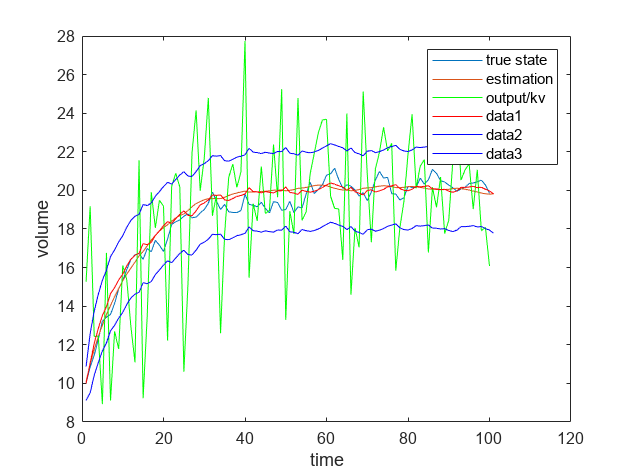

figure(2)
plot(x,'r'); % plot state estimation
hold on;
plot(lb,'b'); % plot lower bounds interval
plot(ub,'b'); % plot upper bound interval

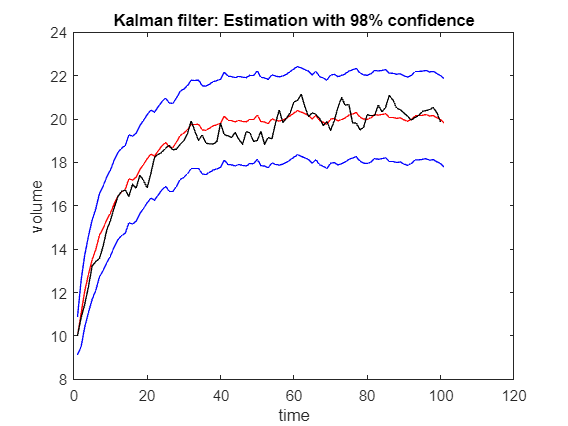

if Q == 0.1 && R == 0.1
    x_kal = x;
    figure
    plot(x,'r'),hold on; % plot state estimation
    plot(lb,'b'); % plot lower bounds interval
    plot(ub,'b'); % plot upper bound interval
    plot(data(:,2),'k')
    title('Kalman filter: Estimation with 98% confidence')
    xlabel('time')
    ylabel('volume')
end

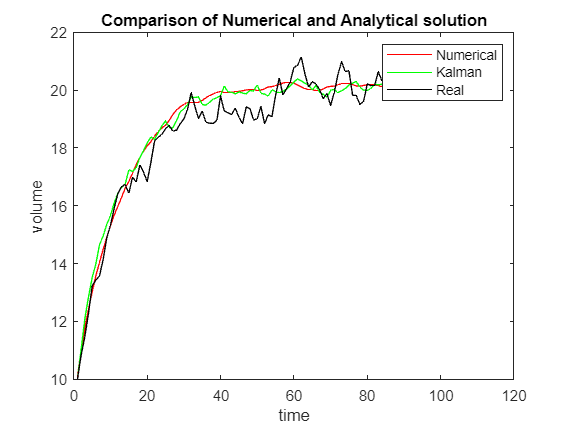

    figure
    plot(x_est_a,'r'), hold on
    plot(x,'g')
    plot(data(:,2),'k')
    legend('Numerical','Kalman','Real')
    title('Comparison of Numerical and Analytical solution')
    xlabel('time')
    ylabel('volume')

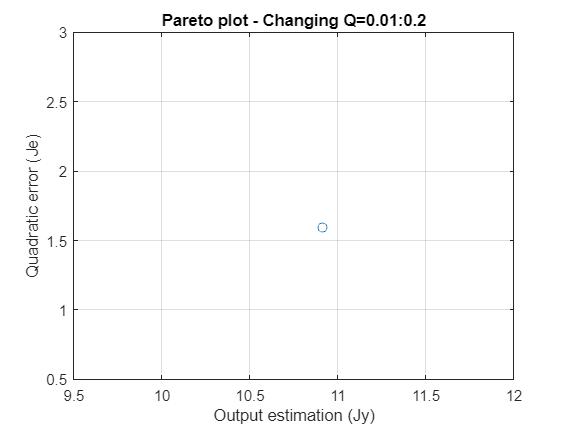

Je=0;
Jy=0;
for k=1:N
    w(k)=x(k+1)-(a*x(k)+b*u(k));    % System noise (disturbance)
    v(k)=y(k)-(c*x(k)+d*u(k));      % Measurement noise
    Je = Je + w(k)'*w(k);   % Quadratic error
    Jy = Jy + v(k)'*v(k);   % Output estimation
end

all_Je_A(p) = Je;
all_Jy_A(p) = Jy;


figure
plot(all_Jy_A,all_Je_A,'o:')
title('Pareto plot - Changing Q=0.01:0.2')
xlabel('Output estimation (Jy)')
ylabel('Quadratic error (Je)')
grid on

syms z
z=vpa(solve(z==Q+(a-a*z*c*(R+c*z*c)^-1*c)*z*a,z,'Real',true))

$$z = \left(\begin{array}{c} -2.1729057180862011395865087288967\\ 0.46021324886601872041966785430985 \end{array}\right)$$

PSS=z(1);
LSS=a*PSS*c*(R+c*PSS*c)^-1;

% variance
Q=0.1;
R=0.1;

A=exp(-kv*T);   % parameter a (using exact discretization)
C=kv;           % parameter c

syms z
z=vpa(solve(z==Q+(A-A*z*C'*inv(R+C*z*C')*C)*z*A',z,'Real',true))

$$z = \left(\begin{array}{c} -2.1729057180862011395865087288967\\ 0.46021324886601872041966785430985 \end{array}\right)$$

PSS=z(2)

$$PSS = 0.46021324886601872041966785430985$$

LSS=A*PSS*C*(R+C*PSS*C)^-1

$$LSS = 0.39809720695226966940828200508746$$

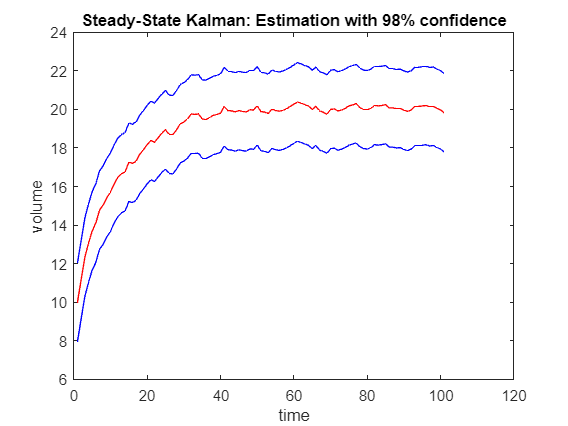

xss=zeros(N+1,1); % initialization of states
lbss=zeros(N+1,1); % lower bounds of states
ubss=zeros(N+1,1); % upper bounds of states
alpha=3; % choose the desired confidence
xss(1)=x1; % initial condition for x;
lbss(1)=x(1)-alpha*sqrt(PSS);
ubss(1)=x(1)+alpha*sqrt(PSS);

for k=1:N % codifying steady state Kalman filter
    xss(k+1)=A*xss(k)+b*u(k)+LSS*(y(k)-C*xss(k));
    lbss(k+1)=xss(k+1)-alpha*sqrt(PSS);
    ubss(k+1)=xss(k+1)+alpha*sqrt(PSS);
end

figure
plot(xss,'r'); % plot state estimation
hold on;
plot(lbss,'b'); % plot lower bounds interval
plot(ubss,'b'); % plot upper bound interval
title('Steady-State Kalman: Estimation with 98% confidence')
xlabel('time')
ylabel('volume')

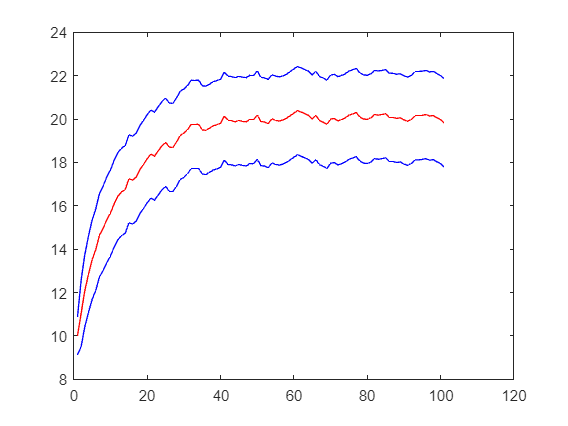

figure
plot(x,'r'); % plot state estimation
hold on;
plot(lb,'b'); % plot lower bounds interval
plot(ub,'b'); % plot upper bound interval

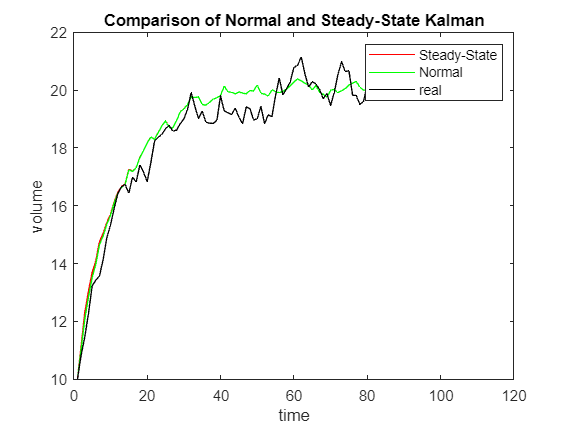

figure
plot(xss,'r'), hold on;
plot(x_kal,'g');
plot(data(:,2),'k');
legend('Steady-State','Normal','real')
title('Comparison of Normal and Steady-State Kalman')
xlabel('time')
ylabel('volume')

% MATLAB Kalman function
SYS=ss(A,[b 1],C,[0 0],-1);
[KEST,L,P] = kalman(SYS,Q,R,'delayed')

KEST =
 
  A = 
          x1_e
   x1_e  0.865
 
  B = 
             u1      y1
   x1_e   1.903  0.3981
 
  C = 
         x1_e
   y1_e   0.1
   x1_e     1
 
  D = 
         u1  y1
   y1_e   0   0
   x1_e   0   0
 
Input groups:              
       Name        Channels
    KnownInput        1    
    Measurement       2    
                           
Output groups:                
         Name         Channels
    OutputEstimate       1    
    StateEstimate        2    
                              
Sample time: unspecified
Discrete-time state-space model.



L = 0.3981

P = 0.4602

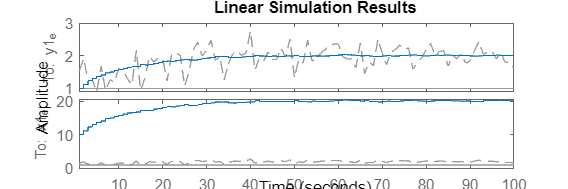

figure('Position',[0 0 1200 400])
lsim(KEST,[u,y],1:100,x1)


T=1; % sample time
kv=0.1; % parameter kv
kb=2; % parameter kb
a=exp(-kv*T); % parameter a (using exact discretization)
b=(1-exp(-kv*T))*kb/kv; % parameter b (using exact discretization)
c=kv; % parameter c
d=0; % parameter d
Q=0.1; % deviation of system noise (disturbance)
R=0.1; % deviation of measurement noise
%LMI solution
A=a'; % Duality principle for observer design
B=c'; % Duality principle for observer design
Y = sdpvar(1,1);
W = sdpvar(1,1);
gamma=sdpvar(1,1);
H=sqrt(Q);
F = Y >= 0;
F = [F, [gamma*eye(1) eye(1);eye(1) Y]>=0];
% LQR LMI
F = [F, [  -Y      Y*A'-W'*B'    Y*H'      W';
         A*Y-B*W      -Y          0         0;
           H*Y         0         -1         0;
            W          0          0    -R^(-1)]  <=  0];

optimize(F,gamma)


 Solver for linear objective minimization under LMI constraints 

 Iterations   :    Best objective value so far 
 
     1
     2
     3                   0.692760
***                 new lower bound:    -2.297868
     4                   0.628974
***                 new lower bound:    -0.414502
     5                   0.499209
***                 new lower bound: 5.959278e-03
     6                   0.473913
***                 new lower bound:     0.395457
     7                   0.462930
***                 new lower bound:     0.424419
     8                   0.461305
***                 new lower bound:     0.454131
     9                   0.460298
***                 new lower bound:     0.456782
    10                   0.460251
***                 new lower bound:     0.459515
    11                   0.460251
***                 new lower bound:     0.460066

 Result:  feasible solution of required accuracy
          best objective value:     0.460251
          guarante

ans = struct with fields:
    yalmipversion: '20230622'
    matlabversion: '9.13.0.2399474 (R2022b) Update 7'
       yalmiptime: 0.4418
       solvertime: 0.0422
             info: 'Successfully solved (LMILAB)'
          problem: 0


L = (value(W)*inv(value(Y)))' % Corrected transpose operator

L = 0.3982

% Implement MHE via numerical optimization
% Estimating x(N+1) from x(1:N) and u(1:N)
load data2; % load data u,x,y (only uses u and y)
N=10; % determine the number of points
u=data(:,1); % read the inputs
y=data(:,3); % read the outputs
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% formulation optimization problem
x_hat = sdpvar(repmat(1,1,N+1),repmat(1,1,N+1));
x_0=sdpvar(1,1);
yd=sdpvar(N,1);
ud=sdpvar(N,1);
objective = (x_0-x_hat{1})'*x_0^(-1)*(x_0-x_hat{1});
constraints = [];
for k = 1:N
objective = objective+...
(x_hat{k+1}-A*x_hat{k}-B*ud(k))'*Q^(-1)*(x_hat{k+1}-A*x_hat{k}-B*ud(k))...
+(yd(k)-C*x_hat{k})'*R^(-1)*(yd(k)-C*x_hat{k});
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% solution of the problem
options = sdpsettings('solver','quadprog');
estimator=optimizer(constraints,objective,options, {yd,ud,x_0},x_hat{N+1});

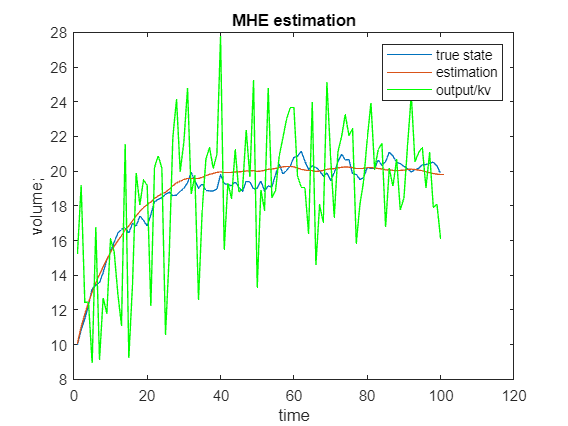

M = 100; % Estimation time
N = 100; % Assuming horizon length for MHE is 10
x_est_mhe = zeros(M+1, 1); % initialization of states

% Initialize the first N state estimation using the result of exercise (a)
x_est_mhe(1:N+1) = x_est(1:N+1);

% Run the MHE in real time
for k = N+1:M
    x_est_mhe(k+1) = estimator(y(k-N:k-1), u(k-N:k-1), x_est_mhe(k-N+1));
end
figure
plot(data(:,2));hold on
plot(x_est_mhe)
plot(y/kv,'g')
title('MHE estimation')
legend('true state','estimation','output/kv')
xlabel('time')
ylabel('volume;')